clear 
clf
% 设定参数
wp = 0.2*pi; % 通带截止频率
rp = 0.25; % 通带波纹
ws = 0.3*pi; % 阻带截止频率
rs = 50; % 阻带衰减

% 计算滤波器阶数
delta_w = ws - wp;
delta_f = delta_w/(2*pi);
N = ceil((rs - 7.95) / (14.36 * delta_f)) + 1

N = 60

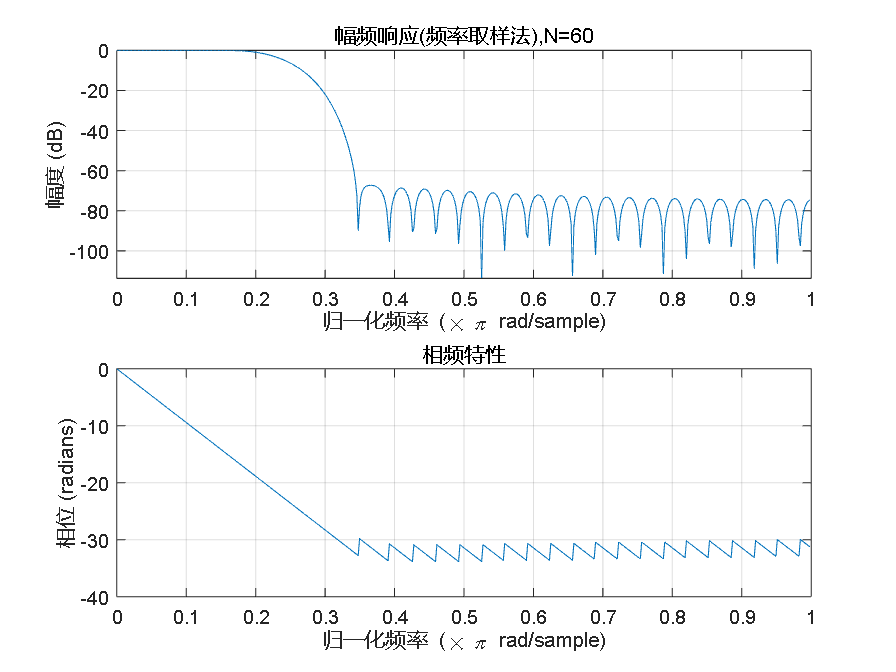


% 设计滤波器
f = [0 wp/pi ws/pi 1];
m = [1 1 0 0];
h = fir2(N, f, m);

% 绘制频率响应
[H, W] = freqz(h, 1, 512);
magnitude = 20*log10(abs(H));
phase = unwrap(angle(H));

figure;
subplot(2,1,1);

plot(W/pi, magnitude);
title('幅频响应(频率取样法),N=60');
xlabel('归一化频率 (\times \pi rad/sample)');
ylabel('幅度 (dB)');

grid on;

subplot(2,1,2);
plot(W/pi, phase);
title('相频特性');
xlabel('归一化频率 (\times \pi rad/sample)');
ylabel('相位 (radians)');
grid on;

%矩形窗函数
clear
clf
% 设定参数
wp = 0.2*pi; % 通带截止频率
rp = 0.25; % 通带波纹
ws = 0.3*pi; % 阻带截止频率
rs = 50; % 阻带衰减

tr=ws-wp;
N=ceil(1.8*pi/tr)+1

N = 19

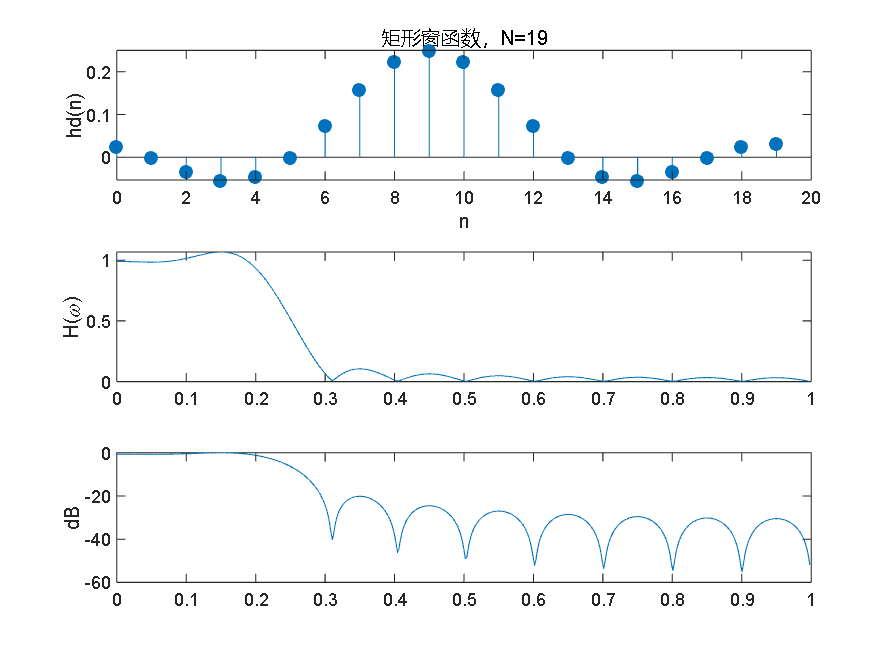


n=0:N;
wc=(wp+ws)/2;
alpha=(N-1)/2;
hd=(wc/pi)*sinc((wc/pi)*(n-alpha));
w_boxcar=boxcar(N+1)';
h=hd.*w_boxcar;

subplot(311)
    stem(n,hd,'filled');
    xlabel('n');
    ylabel('hd(n)');
    title('矩形窗函数，N=19')
[Hr,w1]=zerophase(h);
subplot(312) 
    plot(w1/pi,Hr);
    ylabel('H(\omega)')

[H,w]=freqz(h,1);
subplot(313)
    plot(w/pi,20*log10(abs(H)/max(abs(H))));
    ylabel('dB')

%汉宁窗
clear
clf
% 设定参数

wp = 0.2*pi; % 通带截止频率
rp = 0.25; % 通带波纹
ws = 0.3*pi; % 阻带截止频率
rs = 50; % 阻带衰减

% 计算滤波器阶数
delta_w = ws - wp;
N = ceil(6.2*pi/delta_w)+1

N = 63

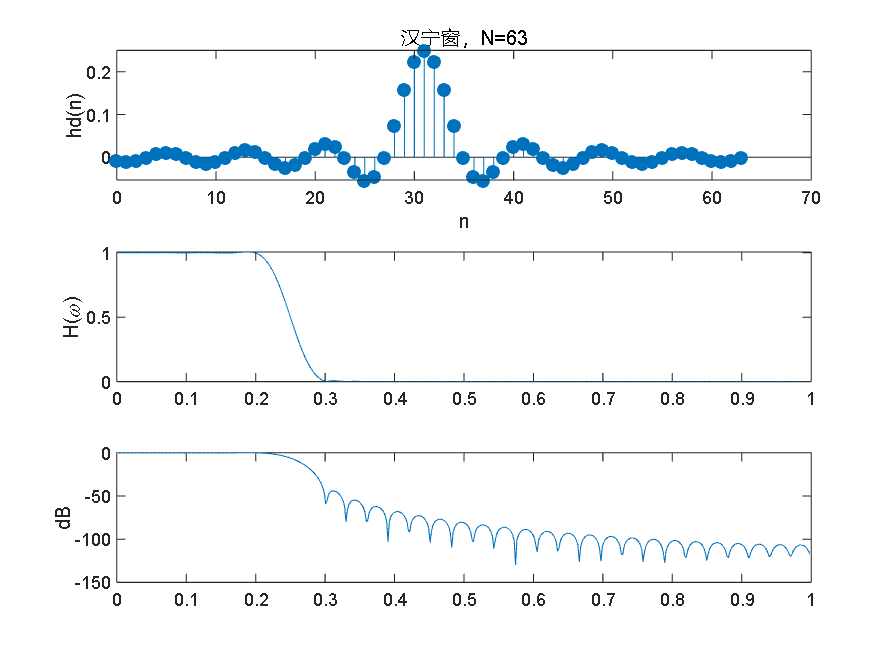

n=0:N;

% 设计滤波器
wc=(wp+ws)/2;
alpha=(N-1)/2;
hd=(wc/pi)*sinc((wc/pi)*(n-alpha));
w_hanning=hanning(N+1)';
h=hd.*w_hanning;
% 绘制频率响应
subplot(311)
    stem(n,hd,'filled');
    xlabel('n');
    ylabel('hd(n)');
    title('汉宁窗，N=63')

[Hr,w1]=zerophase(h);
subplot(312) 
    plot(w1/pi,Hr);
    ylabel('H(\omega)')

[H,w]=freqz(h,1);
subplot(313)
    plot(w/pi,20*log10(abs(H)/max(abs(H))));
    ylabel('dB')

%海明窗
clear
clf
% 设定参数

wp = 0.2*pi; % 通带截止频率
rp = 0.25; % 通带波纹
ws = 0.3*pi; % 阻带截止频率
rs = 50; % 阻带衰减

% 计算滤波器阶数
delta_w = ws - wp;
N = ceil(6.6*pi/delta_w)+1

N = 67

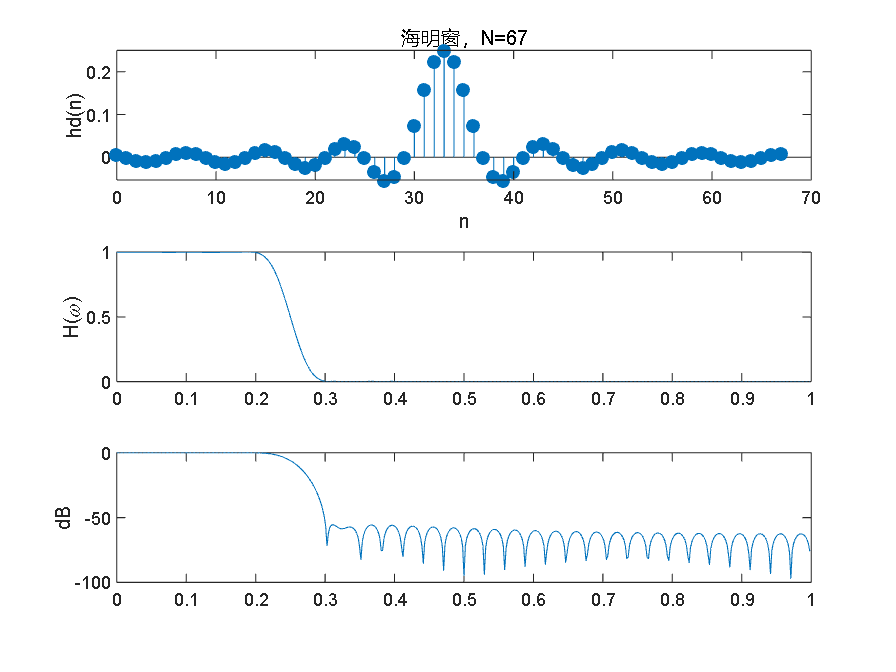

n=0:N;

% 设计滤波器
wc=(wp+ws)/2;
alpha=(N-1)/2;
hd=(wc/pi)*sinc((wc/pi)*(n-alpha));
w_hamming=hamming(N+1)';
h=hd.*w_hamming;
% 绘制频率响应
subplot(311)
    stem(n,hd,'filled');
    xlabel('n');
    ylabel('hd(n)');
    title('海明窗，N=67')

[Hr,w1]=zerophase(h);
subplot(312) 
    plot(w1/pi,Hr);
    ylabel('H(\omega)')

[H,w]=freqz(h,1);
subplot(313)
    plot(w/pi,20*log10(abs(H)/max(abs(H))));
    ylabel('dB')

%布莱克曼
clear
clf
% 设定参数

wp = 0.2*pi; % 通带截止频率
rp = 0.25; % 通带波纹
ws = 0.3*pi; % 阻带截止频率
rs = 50; % 阻带衰减

% 计算滤波器阶数
delta_w = ws - wp;
N = ceil(11*pi/delta_w)+1

N = 111

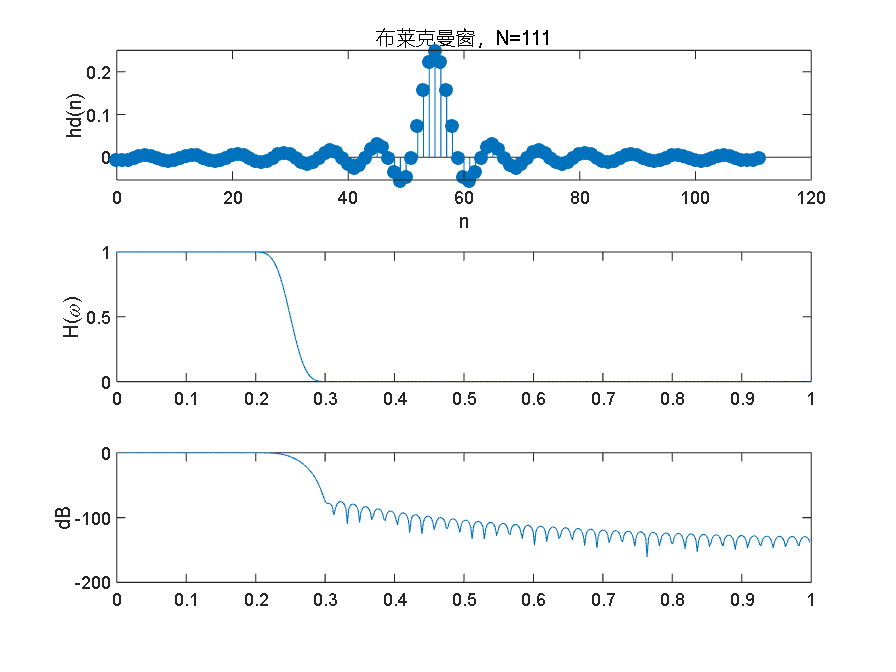

n=0:N;

% 设计滤波器
wc=(wp+ws)/2;
alpha=(N-1)/2;
hd=(wc/pi)*sinc((wc/pi)*(n-alpha));
w_blackman=blackman(N+1)';
h=hd.*w_blackman;
% 绘制频率响应
subplot(311)
    stem(n,hd,'filled');
    xlabel('n');
    ylabel('hd(n)');
    title('布莱克曼窗，N=111')

[Hr,w1]=zerophase(h);
subplot(312) 
    plot(w1/pi,Hr);
    ylabel('H(\omega)')

[H,w]=freqz(h,1);
subplot(313)
    plot(w/pi,20*log10(abs(H)/max(abs(H))));
    ylabel('dB')

%凯瑟
clear
clf
% 设定参数

wp = 0.2*pi; % 通带截止频率
rp = 0.25; % 通带波纹
ws = 0.3*pi; % 阻带截止频率
rs = 50; % 阻带衰减

% 计算滤波器阶数
delta_w = ws - wp;
N = ceil((rs-7.95)/(2.285*delta_w))+1

N = 60

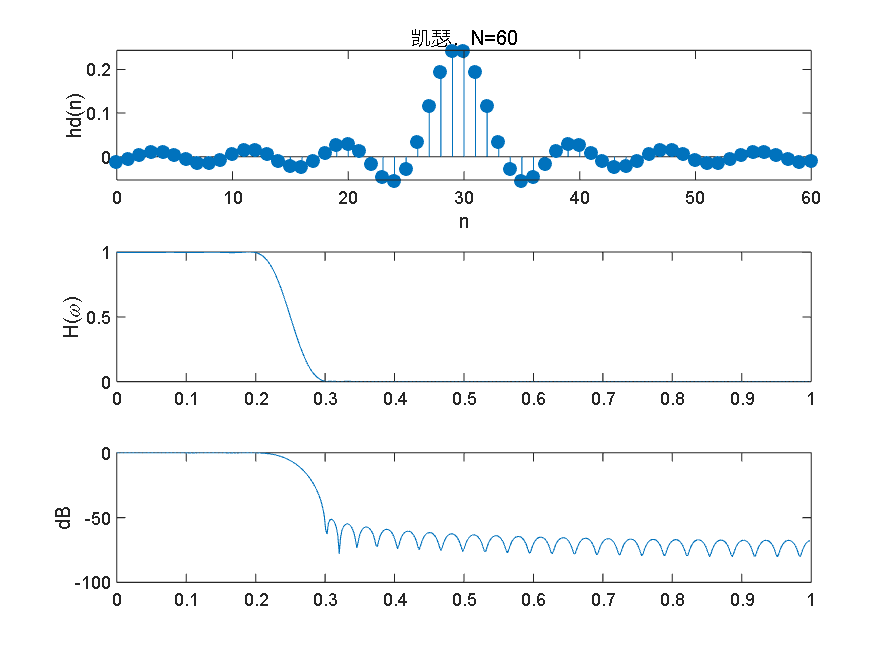

n=0:N;

% 设计滤波器
wc=(wp+ws)/2;
alpha=(N-1)/2;
hd=(wc/pi)*sinc((wc/pi)*(n-alpha));
beta=0.1102*(rs-8.7);
w_kaiser=kaiser(N+1,beta)';
h=hd.*w_kaiser;
% 绘制频率响应
subplot(311)
    stem(n,hd,'filled');
    xlabel('n');
    ylabel('hd(n)');
    title('凯瑟，N=60')

[Hr,w1]=zerophase(h);
subplot(312) 
    plot(w1/pi,Hr);
    ylabel('H(\omega)')

[H,w]=freqz(h,1);
subplot(313)
    plot(w/pi,20*log10(abs(H)/max(abs(H))));
    ylabel('dB')